networks = metropolis_hasting(500);

burned = 0.0152

iterations = 0.0031

trained_network = networks{1,1};


probs = bayesian_classify([0.7;0.3], networks)

probs =      1     0


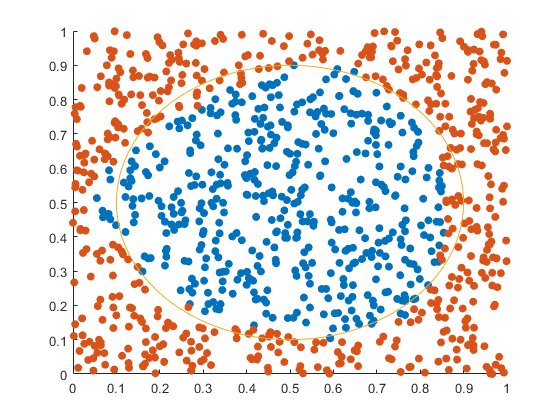

[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,200,"Cirkel");

x1_t = [data_XA data_XB];
x2_t = [data_YA data_YB];
N = length(x1_t);

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:N
    x = [x1_t(c); x2_t(c)];
    probs = bayesian_classify(x,networks);
    if probs(1) >= probs(2)
        XA = [XA, x1_t(c)];
        YA = [YA, x2_t(c)];
    else
        XB = [XB, x1_t(c)];
        YB = [YB, x2_t(c)];
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(XA,YA,'filled')
scatter(XB,YB,'filled')
plot(xunit, yunit);
hold off

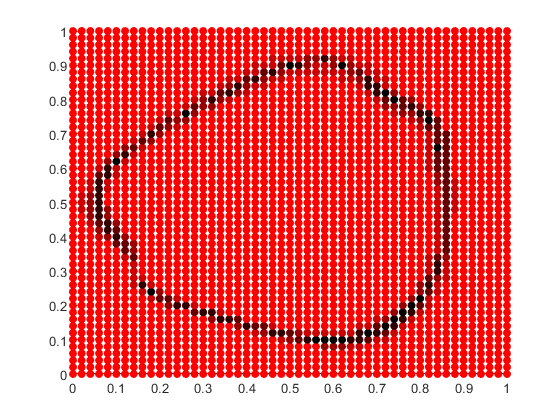

% Uncertainty plotter
% cell(1,n) = x_co
% cell(2,n) = y_co
% cell(3,n) = uncertainty
x_vec = cell(1,length(grid));
y_vec = cell(1,length(grid));
uncert_color = [];

% Classify all data points and assign unceratinty
for i = 1:length(grid)
    x = [grid(1,i); grid(2,i)];
    out = bayesian_classify(x, networks);
    x_vec{1,i} = grid(1,i);
    y_vec{1,i} = grid(2,i);
    uncert_color = [uncert_color; (abs(out(1)-out(2))) 0 0];
end

% Plot uncertaintys using a color gradient
figure
hold on
axis([0 1 0 1])
x_vec = cell2mat(x_vec);
y_vec = cell2mat(y_vec);
scatter(x_vec,y_vec,[],uncert_color,'filled')
hold off